## The impact of the EU-ETS on unemployment in France

### 0. Housekeeping

clear;
close all;

### 1. Data Importation 

Import Data Series:

- `GDP: OECD/QNA/FRA.B1_GE.CQRSA.Q`

- `Inflation: OECD/QNA/FRA.B1_GE.DNBSA.Q`

- `Unemployment: OECD/MEI/FRA.LRUN64TT.STSA.Q`

- `Carbon emissions: OECD/DP_LIVE/FRA.AIREMISSION.GHG.THND_TONNECO2.A`

`Every serie is seasonally adjusted.`

% GDP, deflator, unemployment
[output1,~,T1] = call_dbnomics('OECD/QNA/FRA.B1_GE.CQRSA.Q','OECD/QNA/FRA.B1_GE.DNBSA.Q', 'OECD/MEI/FRA.LRUN64TT.STSA.Q');

% Carbon emissions
[output2,~,T2] = call_dbnomics('OECD/DP_LIVE/FRA.AIREMISSION.GHG.THND_TONNECO2.A');

% Carbon prices
tt_import = readtimetable("carbon_prices_062009_122019.xlsx");

### 2. Data treatment

Retime emissions and carbon prices to quarterly data

% Carbon emissions
dates = datetime(output2(:,1), 'ConvertFrom', 'datenum');
values = output2(:,2);
tt = timetable(dates, values);

ttQ = retime(tt, 'quarterly', 'linear');
output2Q = [datenum(ttQ.dates), ttQ.values];

% Carbon prices
carbon_prices = retime(tt_import(:,4),"quarterly","mean");
outputQ_cp = [datenum(carbon_prices.dates), carbon_prices.pe_obs2];

Merge datasets

output = merged_output(output1, output2Q);
output = merged_output(output, outputQ_cp);

Drop Na values and get index

idx = find(~isnan(sum(output(:,2:end),2)));
output = output(idx,:);
T = T1(idx);
T2 = T

T2 = 1.0e+03 *

    2.0093
    2.0095
    2.0097
    2.0100
    2.0103
    2.0105
    2.0107
    2.0110
    2.0112
    2.0115


Normalize to 2015 prices

id2015 = find(T==2015);
def = output(:,3)/output(id2015,3);

### 3. Create variables of interest

gy_obs  = diff(log(output(:,2)./(def))); % Output growth
pi_obs  = diff(log(def)); % Inflation growth
u_obs = diff(log(output(:,4))); % Unemployment growth
ges_obs = diff(detrend(log(output(:,5)))); % Emission growth
cp_obs = diff(log(output(:,6))); % Carbon price growth
T = T(2:end);

### 4. Test stationnarity

GDP growth:

[h,pValue,stat,cValue] = adftest(gy_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -3.5165

cValue = -1.9475

Inflation:

[h,pValue,stat,cValue] = adftest(pi_obs)

h = logical
   1


pValue = 0.0163

stat = -2.4317

cValue = -1.9475

Unemployment:

[h,pValue,stat,cValue] = adftest(u_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -5.7496

cValue = -1.9475

Carbon emissions:

[h,pValue,stat,cValue] = adftest(ges_obs, alpha=0.1)

h = logical
   1


pValue = 0.0548

stat = -1.9050

cValue = -1.6107

Carbon prices:

[h,pValue,stat,cValue] = adftest(cp_obs)

h = logical
   1


pValue = 1.0000e-03

stat = -4.4954

cValue = -1.9475

### 5. Plot variables

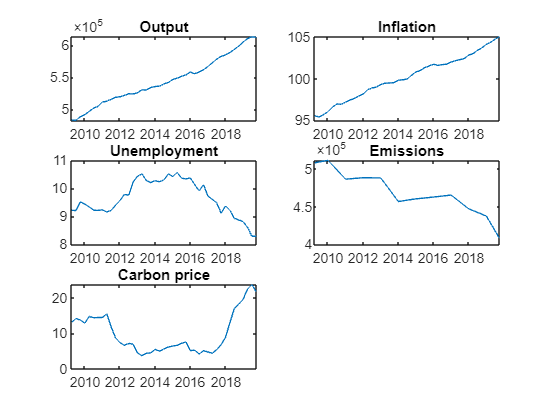

figure;
subplot(3,2,1)
plot(T2,output(:,2))
xlim([min(T2) max(T2)]);
title('Output')
subplot(3,2,2)
plot(T2,output(:,3))
xlim([min(T2) max(T2)]);
title('Inflation')
subplot(3,2,3)
plot(T2,output(:,4))
xlim([min(T2) max(T2)]);
title('Unemployment')
subplot(3,2,4)
plot(T2,output(:,5))
xlim([min(T2) max(T2)]);
title('Emissions')
subplot(3,2,5)
plot(T2,output(:,6))
xlim([min(T2) max(T2)]);
title('Carbon price')

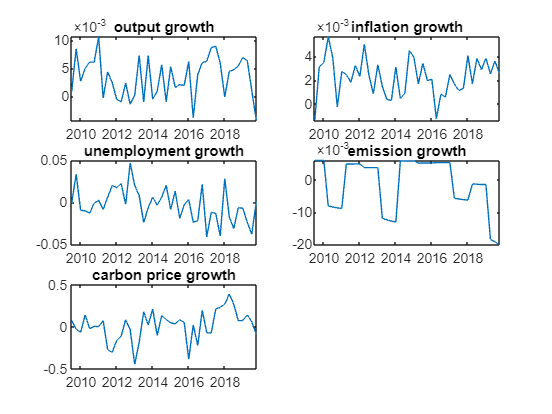


figure;
subplot(3,2,1)
plot(T,gy_obs)
xlim([min(T) max(T)]);
title('output growth')
subplot(3,2,2)
plot(T,pi_obs)
xlim([min(T) max(T)]);
title('inflation growth')
subplot(3,2,3)
plot(T,u_obs)
xlim([min(T) max(T)]);
title('unemployment growth')
subplot(3,2,4)
plot(T,ges_obs)
xlim([min(T) max(T)]);
title('emission growth')
subplot(3,2,5)
plot(T,cp_obs)
xlim([min(T) max(T)]);
title('carbon price growth')

### 6. Save variables in a matrix 

save myobs T gy_obs pi_obs u_obs ges_obs cp_obs;